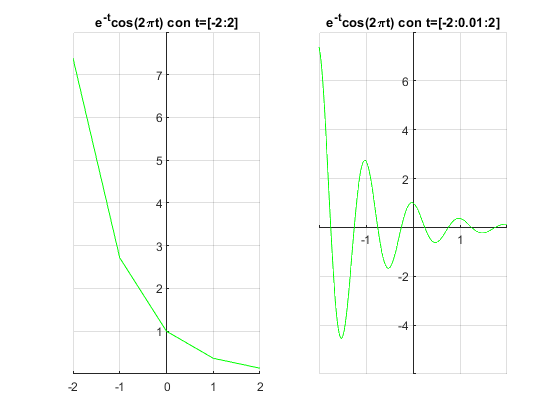

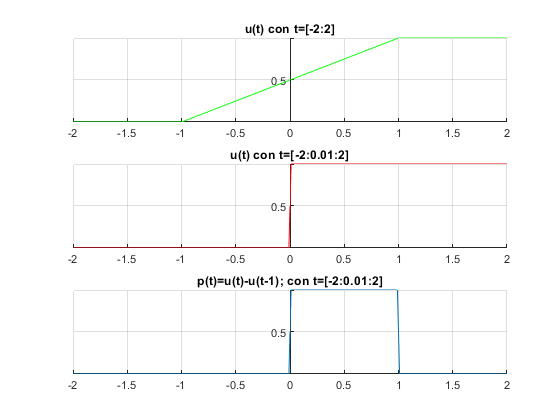

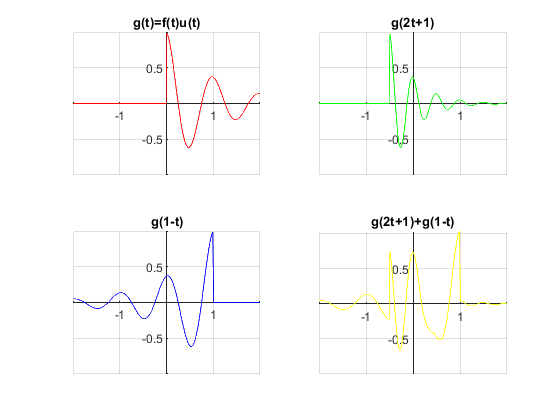

Ex = 0.4295

$$EX = 0.43233235838169365405300025251376$$

clear; clc;

f= @(t) exp(-t).*cos(2*pi*t); %Función anónima para M1.1
u= @(t) heaviside(t); %Función anónima para M1.2
g= @(t) f(t).*u(t); %Funcion anónima para M1.3
x= @(t) exp(-t).*(u(t)-u(t-1)); %Función anónima para M1.4


t1=-2:2;        %1er ejmeplo t un vector de -2 a 2, de 1 en 1
t2=-2:0.01:2;   %2do ejemplo t un vector de -2 a 2, de 0.01 en 0.01

for i=1:4
    switch i
        case 1     %M1.1 Gráfica de e^{-t}cos(2\pit)
            figure
            for j=1:2
                if j==1
                    T=t1;
                else
                    T=t2;
                end
                subplot(1,2,j); plot(T,f(T),'g')
                grid on; ax = gca; ax.Box = 'off';
                ax.XAxisLocation = 'origin';
                ax.YAxisLocation = 'origin';
                if j==1
                    title('e^{-t}cos(2\pit) con t=[-2:2]')
                else
                    title('e^{-t}cos(2\pit) con t=[-2:0.01:2]')
                end
            end
        case 2     %M1.2 Gráfica de u(t)
            figure
            for j=1:3
                subplot(3,1,j);
                if j==1
                    plot(t1,u(t1),'g'); title('u(t) con t=[-2:2]')
                elseif j==2
                    plot(t2,u(t2),'r'); title('u(t) con t=[-2:0.01:2]')
                else
                    p=u(t2)-u(t2-1); plot(t2,p); title('p(t)=u(t)-u(t-1); con t=[-2:0.01:2]')
                end
                grid on; ax = gca; ax.Box = 'off';
                ax.XAxisLocation = 'origin';
                ax.YAxisLocation = 'origin';
            end
        case 3     %M1.3 Gráfica de e^{-t}cos(2\pit)u(t)
            figure
            for j=1:4
                subplot(2,2,j)
                if j==1
                    plot(t2,g(t2),'r'); title('g(t)=f(t)u(t)')
                else
                    plot(t2,g(2*t2 +1),'g'); title('g(2t+1)')
                end
                if j==3
                    plot(t2,g(1-t2),'b'); title('g(1-t)')
                end
                if j==4
                    q=g(2*t2 +1)+g(1-t2);
                    plot(t2,q,'y'); title('g(2t+1)+g(1-t)')
                end
                grid on; ax = gca; ax.Box = 'off';
                ax.XAxisLocation = 'origin';
                ax.YAxisLocation = 'origin';
            end 
        case 4     %M1.4 Integración numerica y estimacion de energía de una señal
            t=0:0.01:1;
            Ex=sum(x(t).*x(t)*0.01)
            syms t %Para calculo simbolico
            f=exp(-2*t)*(heaviside(t)-heaviside(t-1));
            EX=vpa(int(f,t,0,1))
    end
end